# Chapter 2, Section 1 (Part 2)

We focused on $R^2=\left\{\pmatrix{x_1\cr x_2}:\ x_1, x_2\in R\right\}$ in the last section, showing how to multiply a vector $\vec u\in R^2$ by a scalar $c\in R$, and how to add and subtract two vectors $\vec u, \vec v\in R^2$. The rules we showed are the same for vectors in 


$$R^n=\left\{\pmatrix{x_1\cr x_2\cr\vdots\cr x_n}:\ x_1, x_2, \ldots, x_n \in R\right\}$$


# Example #1

Simplify the expression


$$2\pmatrix{-1\cr 2 \cr 3}+3\pmatrix{2\cr -3\cr 1}$$


**Solution:** First, we distribute the scalars times each element of its corresponding vector.


$$2\pmatrix{-1\cr 2 \cr 3}+3\pmatrix{2\cr -3\cr 1}=\pmatrix{-2\cr 4\cr 6}+\pmatrix{6\cr -9\cr 3}$$


Then we calculate the sum by adding the corresponding elements of each vector.


$$\begin{array}{rcl}
2\pmatrix{-1\cr 2 \cr 3}+3\pmatrix{2\cr -3\cr 1}&=&\pmatrix{-2\cr 4\cr 6}+\pmatrix{6\cr -9\cr 3}\\
&=&\pmatrix{4\cr -5\cr 9}
\end{array}$$


And we can check this with Matlab.

u=[-1;2;3];
v=[2;-3;1];
2*u+3*v

ans =      4
    -5
     9


Same answer. :-)

# Example #2

Simplify the expression $2\vec u+3\vec v-4\vec w$, given that:


$$\vec u=\pmatrix{1\cr 2\cr 3\cr 0},\qquad\vec v=\pmatrix{-3\cr 2\cr -1\cr 4},\qquad\text{and}\qquad \vec w=\pmatrix{-1\cr -1\cr 5\cr -1}$$


**Solution: **We'll multiply each vector by the given scalar, then add the resulting vectors.


$$\begin{array}{rcl}
2\vec u+3\vec v-4\vec w
&=&2\pmatrix{1\cr 2\cr 3\cr 0}+3\pmatrix{-3\cr 2\cr -1\cr 4}-4\pmatrix{-1\cr -1\cr 5\cr -1}\\
&=&\pmatrix{2\cr 4\cr 6 \cr 0}+\pmatrix{-9\cr 6\cr -3\cr 12}+\pmatrix{4\cr 4\cr -20\cr 4}\\
&=&\pmatrix{-3\cr14\cr-17\cr 16}
\end{array}$$


And we can check this with Matlab.

u=[1;2;3;0];
v=[-3;2;-1;4];
w=[-1;-1;5;-1];
2*u+3*v-4*w

ans =     -3
    14
   -17
    16


Same answer. :-)

# Properties

Each of the following properties hold in $R^n$. Let $\vec u$, $\vec v$, and $\vec w$ be vectors in $R^n$, and let $c, d\in R$.

- Commutative property: $\vec u+\vec v=\vec u+\vec v$.

- Associative property:  $(\vec u+\vec v)+\vec w=\vec u+(\vec v+\vec w)$.

- Additive identity property: There exists a vector $\vec 0\in R^n$, such that $\vec u+\vec 0=\vec u$ and $\vec 0+\vec u=\vec u$.

- Additive inverse property: For each $\vec u\in R^n$, there exists a $-\vec u\in R^n$ so that $\vec u+(-\vec u)=\vec 0$ and $(-\vec u)+\vec u=\vec 0$.

- $c(\vec u+\vec v)=c\vec u+c\vec v$.

- $(c+d)\vec u=c\vec u+d\vec u$.

- 
$$c(d\vec u)=(cd)\vec u$$


- 
$$(1)\vec u=\vec u$$


Our author offers a proof of property #1, but the others are assigned in the exercises. Let's provide a proof of property #2, so we know what is expected and how to proceed. 

# Example #3

For each $\vec u$, $\vec v$, and $\vec w\in R^n$, prove that $(\vec u+\vec v)+\vec w=\vec u+(\vec v+\vec w)$.

**Proof:** We will start with the left-hand side (or we could start with the right-hand side) and show convincing steps that it is equal to the right-hand side. All of these steps are required.


$$\begin{array}{rcl}
(\vec u+\vec v)+\vec w
&=&\left[\pmatrix{u_1\cr u_2\cr\vdots\cr u_n}+\pmatrix{v_1\cr v_2\cr\vdots\cr v_n}\right]+\pmatrix{w_1\cr w_2\cr\vdots\cr w_n}\\
&=&\pmatrix{u_1+v_1\cr u_2+ v_2\cr \vdots\cr u_n+v_n}+\pmatrix{w_1\cr w_2\cr\vdots\cr uw_n}\\
&=&\pmatrix{(u_1+v_1)+w_1\cr (u_2+ v_2)+w_2\cr \vdots\cr (u_n+v_n)+w_n}
\end{array}$$


The entries of this last result are all real numbers and we know that the associative property holds; that is $(a+b)+c=a+(b+c)$ for any $a, b, c\in R$. Therefore, we can continue with:


$$\begin{array}{rcl}
(\vec u+\vec v)+\vec w&=&\pmatrix{(u_1+v_1)+w_1\cr (u_2+ v_2)+w_2\cr \vdots\cr (u_n+v_n)+w_n}\\
&=&\pmatrix{u_1+(v_1+w_1)\cr u_2+ (v_2+w_2)\cr \vdots\cr u_n+(v_n+w_n)}\\
&=&\pmatrix{u_1\cr u_2\cr\vdots\cr u_n}+\pmatrix{v_1+w_1\cr v_2+w_2\cr \vdots\cr v_n+w_n}\\
&=&\pmatrix{u_1\cr u_2\cr\vdots\cr u_n}+\left[\pmatrix{v_1\cr v_2\cr \vdots\cr v_n}+\pmatrix{w_1\cr w_2\cr \vdots\cr w_n}\right]\\
&=&\vec u+(\vec v+\vec w)
\end{array}$$


Thus, we've shown that $(\vec u+\vec v)+\vec w=\vec u+(\vec v+\vec w)$. We're done.

Let's demonstrate an example of this property with Matlab.

u=[1;2;3]; v=[4;5;6]; w=[7;8;9];
(u+v)+w

ans =     12
    15
    18


u+(v+w)

ans =     12
    15
    18


Both give the same answer. :-)

# Example #4

Can the vector equation


$$c_1\pmatrix{2\cr 1}+c_2\pmatrix{-1\cr 1}=\pmatrix{1\cr 5}$$


be solved for $c_1$ and $c_2$? If so, find $c_1$ and $c_2$.

**Solution:** Let's start with an image. Note that the light gray horizontal and vertical lines represent what we commonly use on graph paper. However, we've added another set of coordinate lines in the direction of $\vec v_1=\pmatrix{2\cr 1}$ and $\vec v_2=\pmatrix{-1\cr 5}$. Using the parallelogram rule, it appears that $2\pmatrix{2\cr 1}+3\pmatrix{-1\cr 1}=\pmatrix{1\cr 5}$. The language that we will use in the next section of our book is "the vector $\pmatrix{1\cr 5}$ is a linear combination of the vectors $\vec v_1=\pmatrix{2\cr 1}$ and $\vec v_2=\pmatrix{-1\cr 5}$."

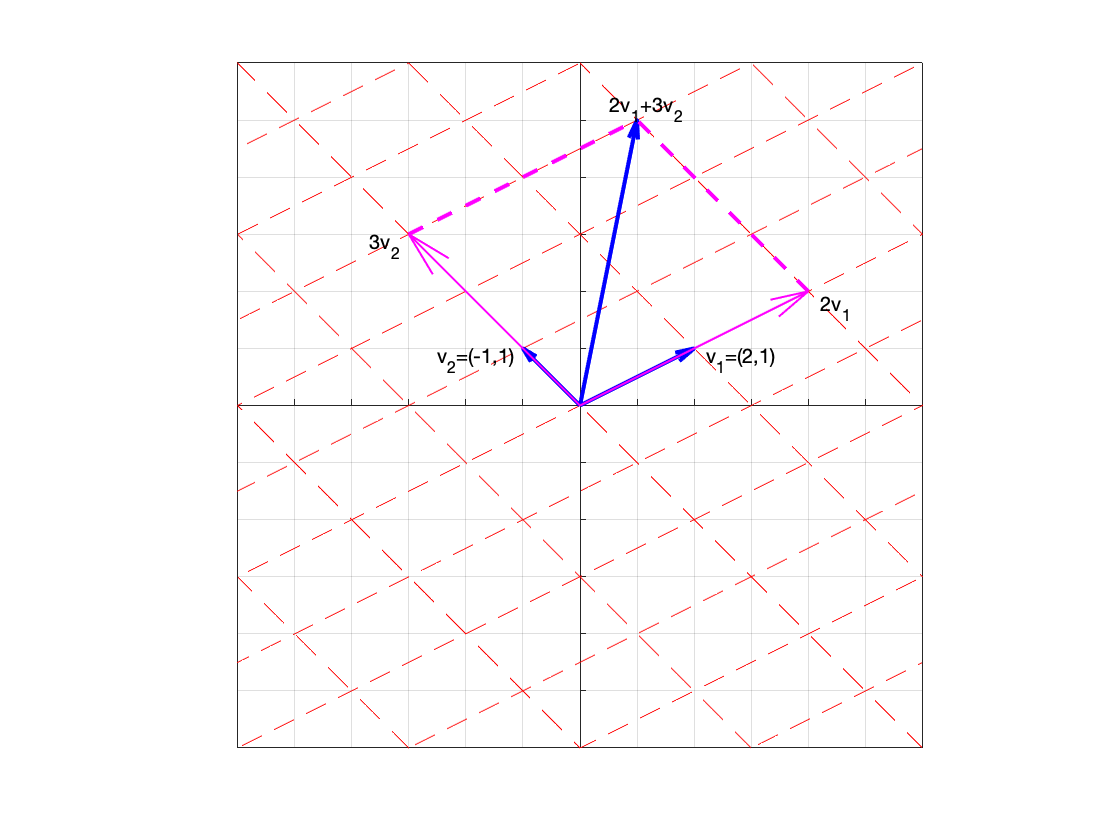

t=linspace(-6,6);
for k=-6:6
    x=-k+2*t;
    y=k+t;
    plot(x,y,'r--')
    hold on
end
for k=-3:3
    x=2*k-t;
    y=k+t;
    plot(x,y,'r--')
end
quiver(0,0,2,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,-1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.8)
quiver(0,0,1,5,0,'LineWidth',2,'Color','b','MaxHeadSize',0.2)
quiver(0,0,4,2,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
quiver(0,0,-3,3,0,'LineWidth',1,'Color','m','MaxHeadSize',0.8)
line([4,1],[2,5],'LineStyle','--','LineWidth',2,'Color','m')
line([-3,1],[3,5],'LineStyle','--','LineWidth',2,'Color','m')
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
axis equal
axis([-6,6,-6,6])
grid on
xticks(-6:6)
yticks(-6:6)
xticklabels({})
yticklabels({})
text(2.2,0.8,'v_1=(2,1)')
text(4.2,1.7,'2v_1')
text(-2.5,0.8,'v_2=(-1,1)')
text(-3.7,2.8,'3v_2')
text(0.5,5.2,'2v_1+3v_2')
hold off

Now, let's do some hand-calculations to see if this is true. First, let's manipulate our equation a bit.


$$\begin{array}{rcl}
c_1\pmatrix{2\cr 1}+c_2\pmatrix{-1\cr 1}&=&\pmatrix{1\cr 5}\\
\pmatrix{2c_1\cr c_1}+\pmatrix{-c_2\cr c_2}&=&\pmatrix{1\cr 5}\\
\pmatrix{2c_1-c_2\cr c_1+c_2}&=&\pmatrix{1\cr 5}
\end{array}$$


Now, in order that these two vectors are equal, their corresponding components must be equal, which gives us the following system of linear equations.


$$\begin{array}{rcl}
2c_1-c_2&=&1\\
c_1+c_2&=&5
\end{array}$$


Let's set up the augmented matrix, then put it in row echelon form and use back substitution to obtain the solution.


$$\begin{array}{rcl}
\pmatrix{2 & -1 & 2\cr 1 & 1 & 5}\ \matrix{R_1\leftrightarrow R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 5\cr 2 & -1 & 1}
\end{array}$$


Then,


$$\begin{array}{rcl}
\pmatrix{1 & 1 & 5\cr 2 & -1 & 1}\ \matrix{~\cr R_2-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 5\cr 0 & -3 & -9}
\end{array}$$


Then,


$$\begin{array}{rcl}
\pmatrix{1 & 1 & 5\cr 0 & -3 & -9}\ \matrix{~\cr (-1/2)R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 5\cr 0 & 1 & 3}
\end{array}$$


This represents the system:


$$\begin{array}{rcl}
c_1+c_2&=&5\\
c_2&=&3
\end{array}$$


Substituting $c_2=3$ in the first equation gives us $c_1=2$. Therefore,


$$2\pmatrix{2\cr 1}+3\pmatrix{-1\cr 1}=\pmatrix{1\cr 5}$$


which agrees with our image above.

# Example #5

Given that


$$\vec e_1=\pmatrix{1\cr 0 \cr 0},\qquad\vec e_2=\pmatrix{0\cr 1\cr 0}, \qquad\text{and}\qquad \vec e_3=\pmatrix{0\cr 0\cr 1}$$


write the vector $\vec v=\pmatrix{2\cr 3\cr 5}$ as a linear combination of the vectors $\vec e_1, \vec e_2$, and $\vec e_3$.

**Solution:** Let's start with an image.

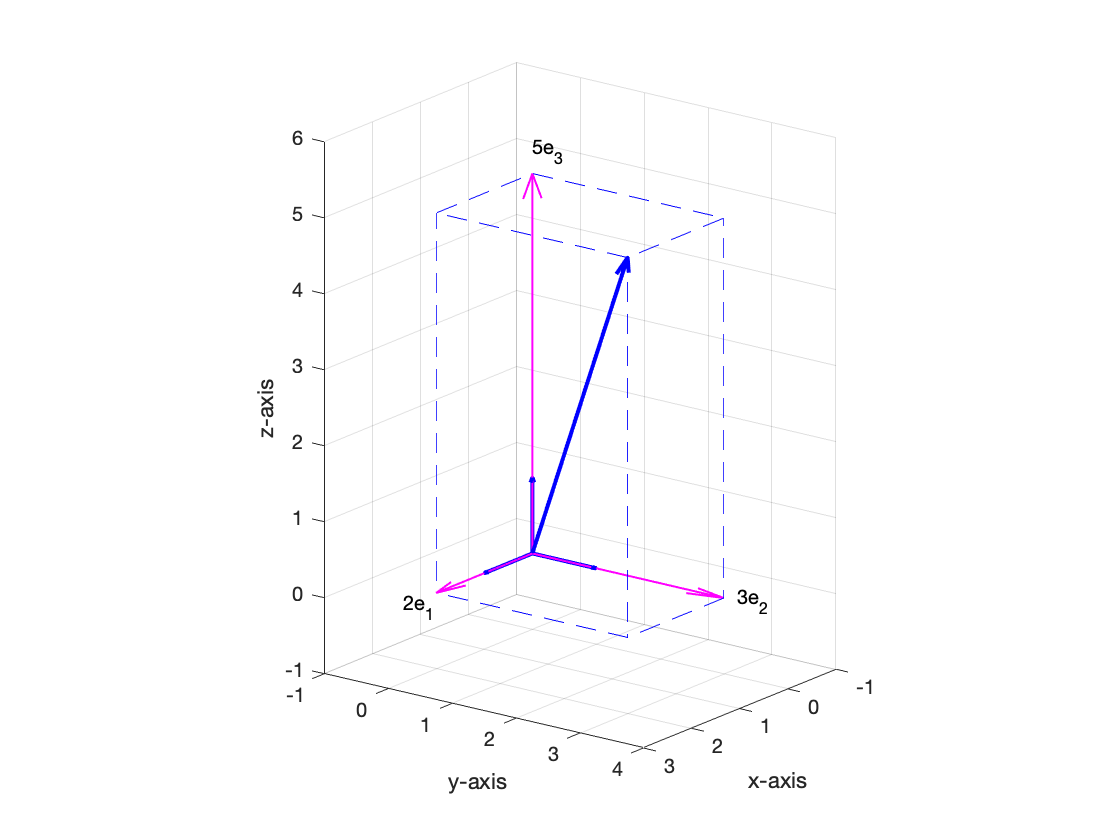

quiver3(0,0,0,1,0,0,0,'LineWidth',2,'Color','b')
hold on
quiver3(0,0,0,0,1,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,2,3,5,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','m','MaxHeadSize',0.7)
quiver3(0,0,0,0,3,0,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,5,0,'LineWidth',1,'Color','m','MaxHeadSize',0.2)
plot3([2,2,0],[0,3,3],[0,0,0],'b--')
plot3([0,2,2,0,0],[0,0,3,3,0],[5,5,5,5,5],'b--')
plot3([2,2],[0,0],[0,5],'b--')
plot3([2,2],[3,3],[0,5],'b--')
plot3([0,0],[3,3],[0,5],'b--')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
axis equal
axis([-1,3,-1,4,-1,6])
hold off
view(127,18)
text(2.7,0,0,'2e_1')
text(0,3.2,0,'3e_2')
text(0,0,5.3,'5e_3')

The small blue vectors are $\vec e_1$, $\vec e_2$, and $\vec e_3$, located on the $x$, $y$, and $z$ axes. The long blue vector is the vector $(2,3,5)^T$. The magenta colored vectors are $2\vec e_1$, $3\vec e_2$, and $5\vec e_3$. Note how we added them, using what is known as the parllelepiped method, which is very similar to the parallelogram method of adding two vectors. Thus, we've shown visual evidence that:


$$2\pmatrix{1\cr 0\cr 0}+3\pmatrix{0\cr 1\cr 0}+5\pmatrix{0\cr 0 \cr 1}=\pmatrix{2\cr 3\cr 5}$$


Note that it is quite simple to verify this mentally, multiplying the scalar times each vector, then adding the results.

# Example #6

Write the vector equation


$$c_1\pmatrix{1\cr -2\cr 1}+c_2\pmatrix{1\cr 0\cr 1}+c_3\pmatrix{2\cr1\cr2}=\pmatrix{1\cr -3\cr 1}$$


as a system of linear equations, then solve the system.

**Solution: **Let's do a little manipulation.


$$\begin{array}{rcl}
c_1\pmatrix{1\cr -2\cr 1}+c_2\pmatrix{1\cr 0\cr 1}+c_3\pmatrix{2\cr1\cr2}&=&\pmatrix{1\cr -3\cr 1}\\
\pmatrix{c_1\cr -2c_1\cr c_1}+\pmatrix{c_2\cr 0\cr c_2}+\pmatrix{2c_3\cr c_3\cr 2c_3}&=&\pmatrix{1\cr -3\cr 1}\\
\pmatrix{c_1+c_2+2c_3\cr -2c_1+c_3\cr c_1+c_2+2c_3}&=&\pmatrix{1\cr -3\cr 1}\\
\end{array}
$$


Equating the corresponding components of these two vectors gives us a system of three linear equations.


$$\begin{array}{rcl}
c_1+c_2+2c_3&=&1\\
-2c_1+c_3&=&-3\\
c_1+c_2+2c_3&=&1
\end{array}$$


Now we will set up an augmented matrix, put the matrix in reduced row echelon form.


$$\pmatrix{1 & 1 & 2 & 1\cr -2 & 0 & 1 & -3\cr 1 & 1 & 2 & 1}\ \matrix{~\cr R_2+2R_1\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 2 & 1\cr0 & 2 & 5 & -1\cr 0  & 0  & 0 & 0}$$


Next,


$$\pmatrix{1 & 1 & 2 & 1\cr0 & 2 & 5 & -1\cr 0  & 0  & 0 & 0}\ \matrix{~\cr (1/2)R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 2 & 1\cr0 & 1 & 5/2 & -1/2\cr 0  & 0  & 0 & 0}$$


Next,


$$\pmatrix{1 & 1 & 2 & 1\cr0 & 1 & 5/2 & -1/2\cr 0  & 0  & 0 & 0}\ \matrix{R_1-R2\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 &-1/2 & 3/2\cr0 & 1 & 5/2 & -1/2\cr 0  & 0  & 0 & 0}$$


Let's check this with Matlab.

A=[1 1 2 1;-2 0 1 -3;1 1 2 1];
rref(sym(A))

$$ans = \left(\begin{array}{cccc} 1 & 0 & -\frac{1}{2} & \frac{3}{2}\\ 0 & 1 & \frac{5}{2} & -\frac{1}{2}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Same answer. 


$$\pmatrix{[1] & 0 &-1/2 & 3/2\cr0 & [1] & 5/2 & -1/2\cr 0  & 0  & 0 & 0}$$


So, our pivot variables are $c_1$ and $c_2$, and $c_3$ is a free variable. This gives us the following system of equations.


$$\begin{array}{rcl}
c_1-\frac12c_3&=&\frac32\\
c_2+\frac52c_3&=&-\frac12
\end{array}$$


Now, we solve for the pivot variables in terms of the free variable $c_3$.


$$\begin{array}{rcl}
c_1&=&\frac12c_3+\frac32\\
c_2&=&\frac52c_3-\frac12\\
c_3&=&\text{free}
\end{array}$$


If we let $c_3=t$, then we have an infinite number of solutions


$$\pmatrix{c_1\cr c_2\cr c_3}=\pmatrix{\frac12t+\frac32\cr \frac52t-\frac12\cr t}$$


where $t$ is any free real number. What does this collection of solutions look like?

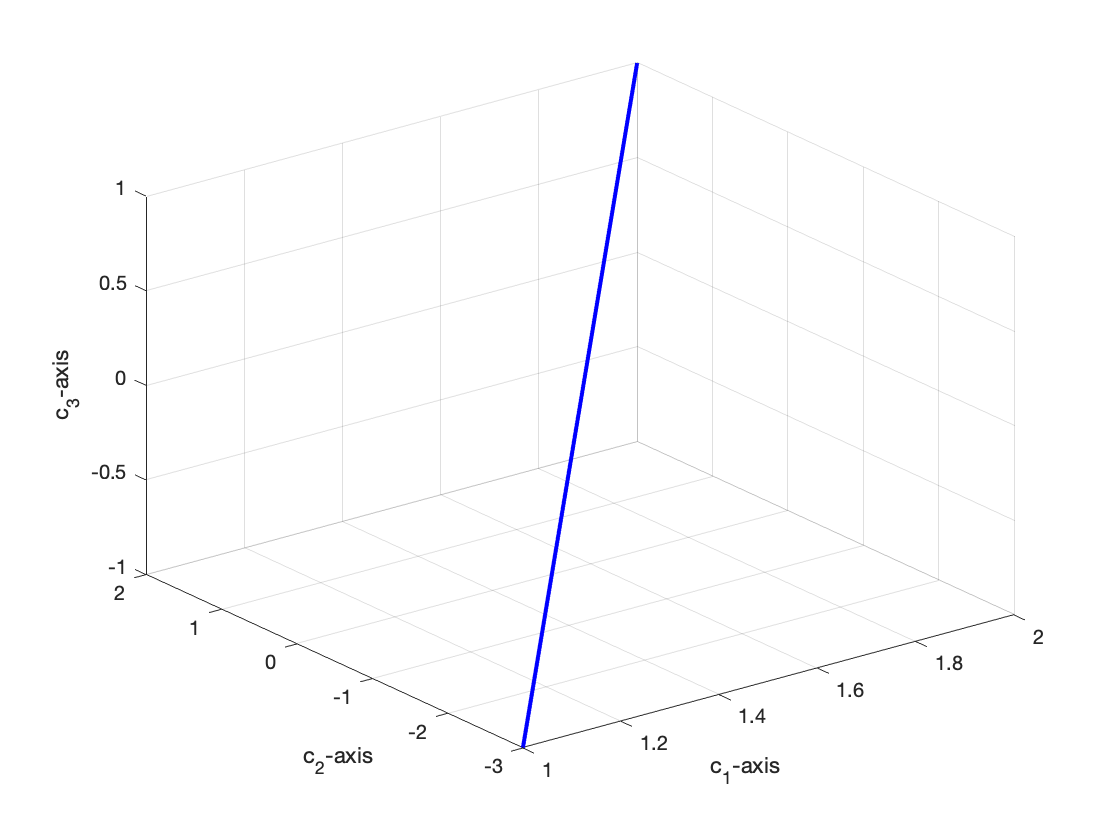

t=linspace(-1,1);
x=t/2+3/2; y=5*t/2-1/2; z=t;
plot3(x,y,z,'LineWidth',2,'Color','b')
grid on
xlabel('c_1-axis')
ylabel('c_2-axis')
zlabel('c_3-axis')

The collection of solutions lie on a line in three space. 

# Example #7

Given the vectors


$$\vec v_1=\pmatrix{1\cr 1\cr 2},\qquad\vec v_2=\pmatrix{2\cr 1\cr 1},\qquad\text{and}\qquad \vec v_3=\pmatrix{3\cr 2\cr 3}$$


find all the vectors


$$\vec v=\pmatrix{a\cr b\cr c}$$


so that the vector equation $c_1\vec v_1+c_2\vec v_2+c_2\vec v_3=\vec v$ can be solved.

**Solution: **Let's manipulate our vector equation a bit.


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+c_2\vec v_3&=&\vec v\\
c_1\pmatrix{1\cr 1\cr 2}+c_2\pmatrix{2\cr 1\cr 1}+c_3\pmatrix{3\cr 2\cr 3}&=&\pmatrix{a\cr b\cr c}\\
\pmatrix{c_1+2c_2+3c_3\cr c_1+c_2+2c_3\cr 2c_1+c_2+3c_3}&=&\pmatrix{a\cr b\cr c}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & 2 & 3 & a\cr 1 & 1 & 2 & b\cr 2 & 1 & 3 & c}\ \matrix{~\cr R_2-R_1\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 3 & a\cr 0 & -1 & -1 & b-a\cr 0 & -3 & -3 & c-2a}$$


Let's check this step with Matlab.

syms a b c
A=[1 2 3 a;1 1 2 b;2 1 3 c];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-r1;r3-2*r1]

$$A = \left(\begin{array}{cccc} 1 & 2 & 3 & a\\ 0 & -1 & -1 & b-a\\ 0 & -3 & -3 & c-2\,a \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 2 & 3 & a\cr 0 & -1 & -1 & b-a\cr 0 & -3 & -3 & c-2a}\ \matrix{~\cr -1R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 3 & a\cr 0 & 1 & 1 & a-b \cr 0 & -3 & -3 & c-2a}$$


Let's check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;-r2;r3]

$$A = \left(\begin{array}{cccc} 1 & 2 & 3 & a\\ 0 & 1 & 1 & a-b\\ 0 & -3 & -3 & c-2\,a \end{array}\right)$$

Correct. Next,


$$\pmatrix{1 & 2 & 3 & a\cr 0 & 1 & 1 & a-b \cr 0 & -3 & -3 & c-2a}\ \matrix{~\cr~\cr R_3+3R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 3 & a\cr 0 & 1 & 1 & a-b \cr 0 & 0 & 0 & a-3b+c}$$


Let's check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3+3*r2]

$$A = \left(\begin{array}{cccc} 1 & 2 & 3 & a\\ 0 & 1 & 1 & a-b\\ 0 & 0 & 0 & a-3\,b+c \end{array}\right)$$

Correct. Now, there will be no solutions if $a-3b+c\ne 0$, We will have an infinite number of solutions if $a-3b+c=0$. What will these solutions look like? If we solve $a-3b+c=0$ for $a$, then $b$ and $c$ are free.


$$\begin{array}{rcl}
a&=&3b-c\\
b&=&\text{free}\\
c&=&\text{free}
\end{array}$$


If we let $s=b$ and $t=c$, then all solutions can be described as:


$$\pmatrix{a\cr b\cr c}=\pmatrix{3s-t\cr s\cr t}$$


where $s$ and $t$ are free to be any real number at all. Using our properties of vectors, this last expression can be written as follows.


$$\begin{array}{rcl}
\pmatrix{a\cr b\cr c}&=&\pmatrix{3s\cr s\cr 0}+\pmatrix{-t\cr 0\cr t}\\
\pmatrix{a\cr b\cr c}&=&s\pmatrix{3\cr 1\cr 0}+t\pmatrix{-1\cr 0\cr 1}
\end{array}$$


So we can see that our vector equation will have solutions only if the vector $(a,b,c)^T$ can be written as a linear combination of the two vectors $(3,1,0)^T$ and $(-1,0,1)^T$. Now, what do all linear combinations of these two vectors look like? Because of our parallelogram method for adding two vectors, we would expect it would be a plane containing the two vectors $(3,1,0)^T$ and $(-1,0,1)^T$.

Let's choose some $s$ and $t$ values between $-2$ and 2, then set up a grid of S and T values.

s=linspace(-2,2,20);
t=linspace(-2,2,20);
[S,T]=meshgrid(s,t);

Now, let's compute A, B, and C and use Matlab's mesh command to perform the plot.

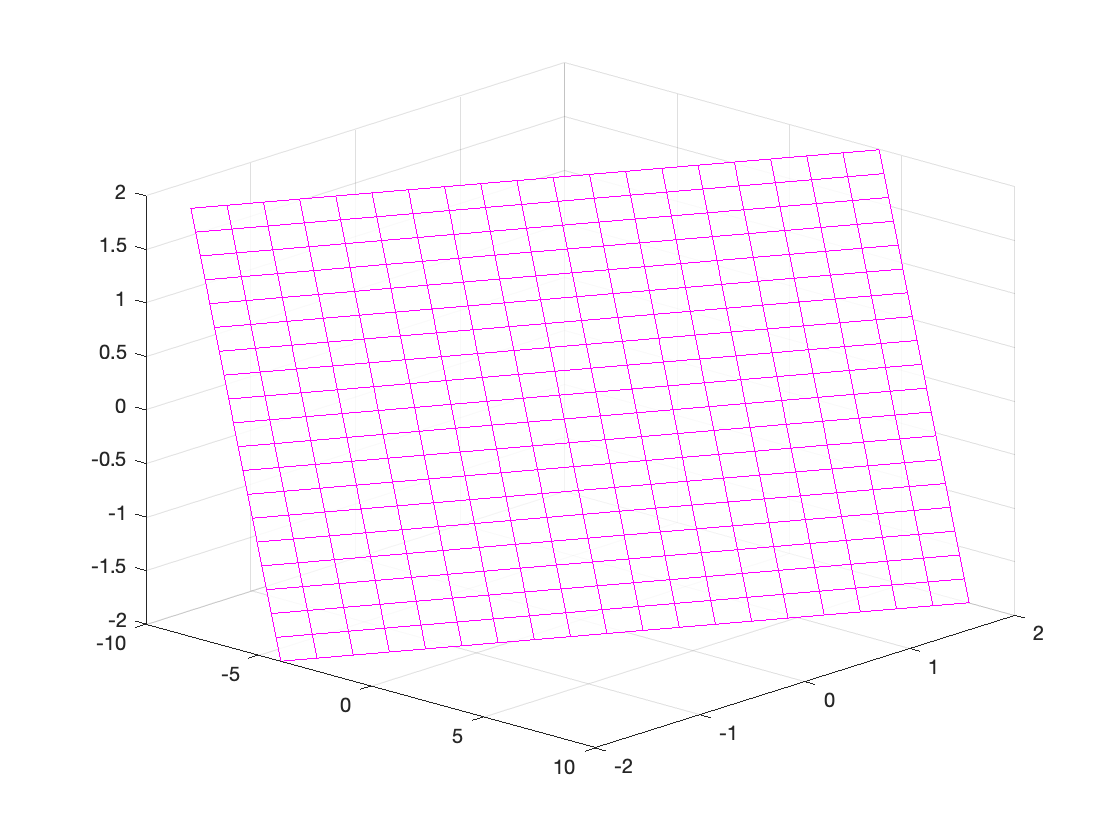

figure
A=3*S-T;
B=S;
C=T;
mesh(A,B,C,'EdgeColor','m','FaceAlpha',0.8)
view(43,23)

We got a plane! Let's add our vectors $(3,1,0)^T$ and $(-1,0,1)^T$ to our image and prettify our image.

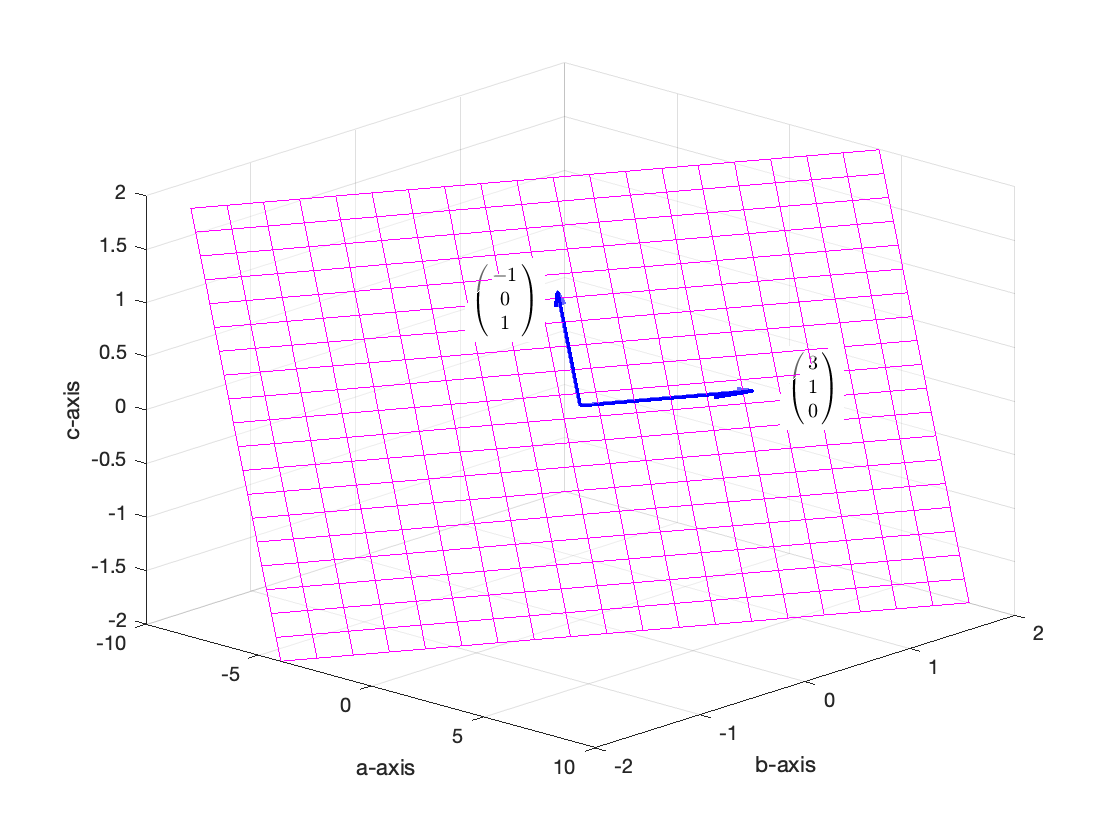

figure
mesh(A,B,C,'EdgeColor','m','FaceAlpha',0.4)
hold on
quiver3(0,0,0,3,1,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver3(0,0,0,-1,0,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
xlabel('a-axis')
ylabel('b-axis')
zlabel('c-axis')
text(3.6,1.2,0,'$$\pmatrix{3\cr1\cr0}$$',...
    'Interpreter','Latex','BackgroundColor','white')
text(-2.5,-0.5,1,'$$\pmatrix{-1\cr0\cr1}$$',...
    'Interpreter','Latex','BackgroundColor','white')
view(43,23)

If we let $(a,b,c)$ be any point on this plane, that is, a linear combination of the vectors $(3,1,0)^T$ and $(-1,0,1)^T$, then our system will have a solution.